## **OFDM Simulation**

Dua Kaurejo 

**Objectives**

- Simulate an OFDM system for digital communication.

- Analyze its performance under different conditions (e.g., noise, channel effects).

- Implement basic channel estimation.

**Key Concepts**

**Orthogonal Frequency Division Multiplexing (OFDM) **is a technique for transmitting data efficiently by splitting it into parallel streams, modulating them onto orthogonal subcarriers, and combining them in the frequency domain to maximize spectral efficiency and robustness against channel distortions. 

- **Subcarriers: **Independent, orthogonal frequency components used to carry portions of the data, minimizing inter-carrier interference. 

- **IFFT/FFT**: Converts data between time and frequency domains; IFFT generates the OFDM signal, and FFT demodulates it at the receiver. 

- **Cyclic Prefix**: A guard interval added to each OFDM symbol to mitigate intersymbol interference (ISI) caused by multipath. 

- **Symbol Mapping (QPSK, QAM)**: Data bits are mapped onto symbols using modulation schemes like QPSK or QAM. Symbols represent the smallest units of modulated data transmitted over each subcarrier. 

clear; close all; clc;
rng(42); % fixed seed for reproducibility


**start**

% Transmitter
% Parameters
N = 64; % FFT size (number of subcarriers)
M = 4; % Modulation order (16-QAM)
numSymbols = 100; % Number of OFDM symbols
cyclicPrefixLength = N / 4; % Cyclic prefix length
SNR = 40; % Signal-to-Noise Ratio in dB

% Generate random binary data for data subcarriers
data = randi([0 1], numSymbols * N * log2(M), 1);

% Map data to QAM symbols
symbolIndices = bi2de(reshape(data, [], log2(M)), 'left-msb');
qamSymbols = qammod(symbolIndices, M, 'gray');

% Reshape QAM symbols into OFDM symbols
ofdmSymbols = reshape(qamSymbols, N, []);

% Perform IFFT
timeDomainSymbols = ifft(ofdmSymbols, N);

% Add cyclic prefix
cyclicPrefix = timeDomainSymbols(end-cyclicPrefixLength+1:end, :);
ofdmSymbolsWithCP = [cyclicPrefix; timeDomainSymbols];

% Serialize for transmission
transmittedSignal = ofdmSymbolsWithCP(:);

% Channel Model
fs = 1e6; % Sampling frequency (Hz)
fd = 40; % Doppler frequency (Hz)
delayVector = [0 1.5 3] * 1e-6; % Path delays
gainVector = [0 -5 -10]; % Path gains (dB)

T_CP = cyclicPrefixLength/fs; 
if max(delayVector) > T_CP
    error('The maximum delay exceeds the cyclic prefix duration!');
else
    disp('Delays align with the cyclic prefix.');
end

Delays align with the cyclic prefix.


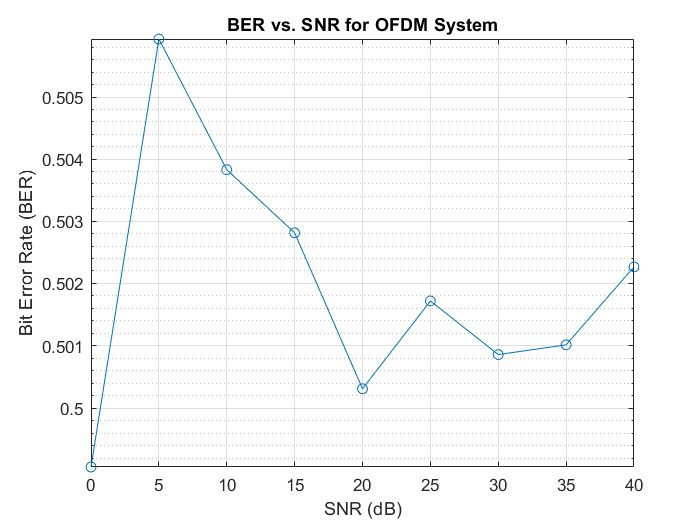


rayleighChannel = comm.RayleighChannel('SampleRate', fs, 'PathDelays', delayVector, ...
    'AveragePathGains', gainVector, 'MaximumDopplerShift', fd);

% Generate channel impulse response
impulse = [1; zeros(N-1, 1)]; % Delta function
h = rayleighChannel(impulse);
reset(rayleighChannel); % Reset channel for consistency

% Apply channel effects
fadedSignal = rayleighChannel(transmittedSignal);
noisySignal = awgn(fadedSignal, SNR, 'measured');

% Receiver
receivedSignal = reshape(noisySignal, N + cyclicPrefixLength, []);
receivedWithoutCP = receivedSignal(cyclicPrefixLength+1:end, :);
receivedFrequencyDomain = fft(receivedWithoutCP, N);

equalizedSymbols = receivedFrequencyDomain ./ fft(h, N);

% Demodulation
demodulatedIndices = qamdemod(equalizedSymbols, M, 'gray');
demodulatedData = de2bi(demodulatedIndices, log2(M), 'left-msb');
demodulatedDataStream = reshape(demodulatedData.', [], 1);

% BER Calculation
originalData = data(1:length(demodulatedDataStream));
bitErrors = sum(originalData ~= demodulatedDataStream);
BER = bitErrors / length(originalData);

% Display results
%disp(['Bit Error Rate (BER): ', num2str(BER)]);

% Performance Analysis
SNR_values = 0:5:40; % Range of SNR values
BER_values = zeros(size(SNR_values));

for i = 1:length(SNR_values)
    % Add noise for current SNR
    noisySignal = awgn(fadedSignal, SNR_values(i), 'measured');

    % Receiver processing
    receivedSignal = reshape(noisySignal, N + cyclicPrefixLength, []);
    receivedWithoutCP = receivedSignal(cyclicPrefixLength+1:end, :);
    receivedFrequencyDomain = fft(receivedWithoutCP, N);

    % Equalization
    equalizedSymbols = receivedFrequencyDomain ./ fft(h, N);

    % Demodulation
    demodulatedIndices = qamdemod(equalizedSymbols, M, 'gray');
    demodulatedData = de2bi(demodulatedIndices, log2(M), 'left-msb');
    demodulatedDataStream = reshape(demodulatedData.', [], 1);

    % Calculate BER
    originalData = data(1:length(demodulatedDataStream));
    bitErrors = sum(originalData ~= demodulatedDataStream);
    BER_values(i) = bitErrors / length(originalData);
end

% Plot BER vs. SNR
figure;
semilogy(SNR_values, BER_values, '-o');
grid on;
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('BER vs. SNR for OFDM System');

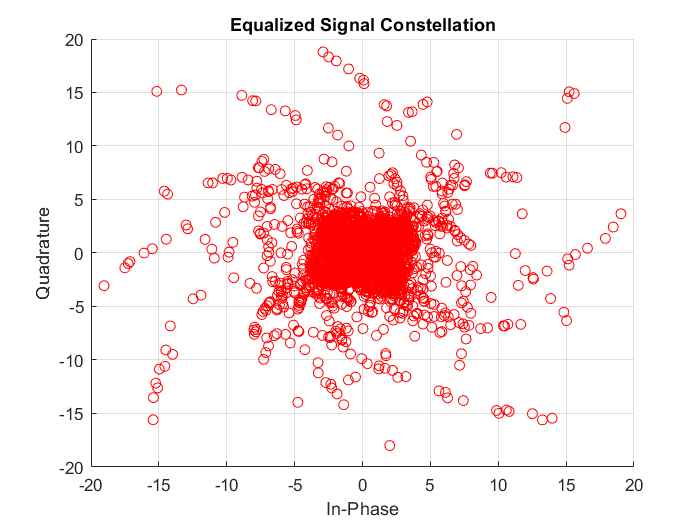


% Visualization
figure;
scatter(real(equalizedSymbols(:)), imag(equalizedSymbols(:)), 'r');
grid on;
xlabel('In-Phase');
ylabel('Quadrature');
title('Equalized Signal Constellation');